clc;

r_earth = 6371000; % unit = m
G = 6.6743 * 10e-11;

% coordinates of satellite
orbit_gracefo1 = importdata("E:/lhsPrograms/gracefo_dataset/gracefo_1B_2020-07-02_RL04.ascii.noLRI/GNV1B_2020-07-02_C_04.txt", " ", 148);
orbit_gracefo2 = importdata("E:/lhsPrograms/gracefo_dataset/gracefo_1B_2020-07-02_RL04.ascii.noLRI/GNV1B_2020-07-02_D_04.txt", " ", 148);
coor_sate1 = orbit_gracefo1.data(2548: 5378, 1: 3);
coor_sate2 = orbit_gracefo2.data(2548: 5378, 1: 3);

% coordinates of sources
s_lat = linspace(0, 0, 1);
s_lon = linspace(18.35-15, 18.35+15, 200);
s_hgt = linspace(0, 0, 1);
s_mas = 100e3*100e3 * 10 * 100; % unit = kg

s_coor = [];
for i = 1: 1
    for j = 1: 200
        for k = 1: 1
            s_coor = [s_coor; [s_lat(i), s_lon(j), s_hgt(k)]];
        end
    end
end
writematrix(s_coor, "../output/coordinates_sources_syn.txt");

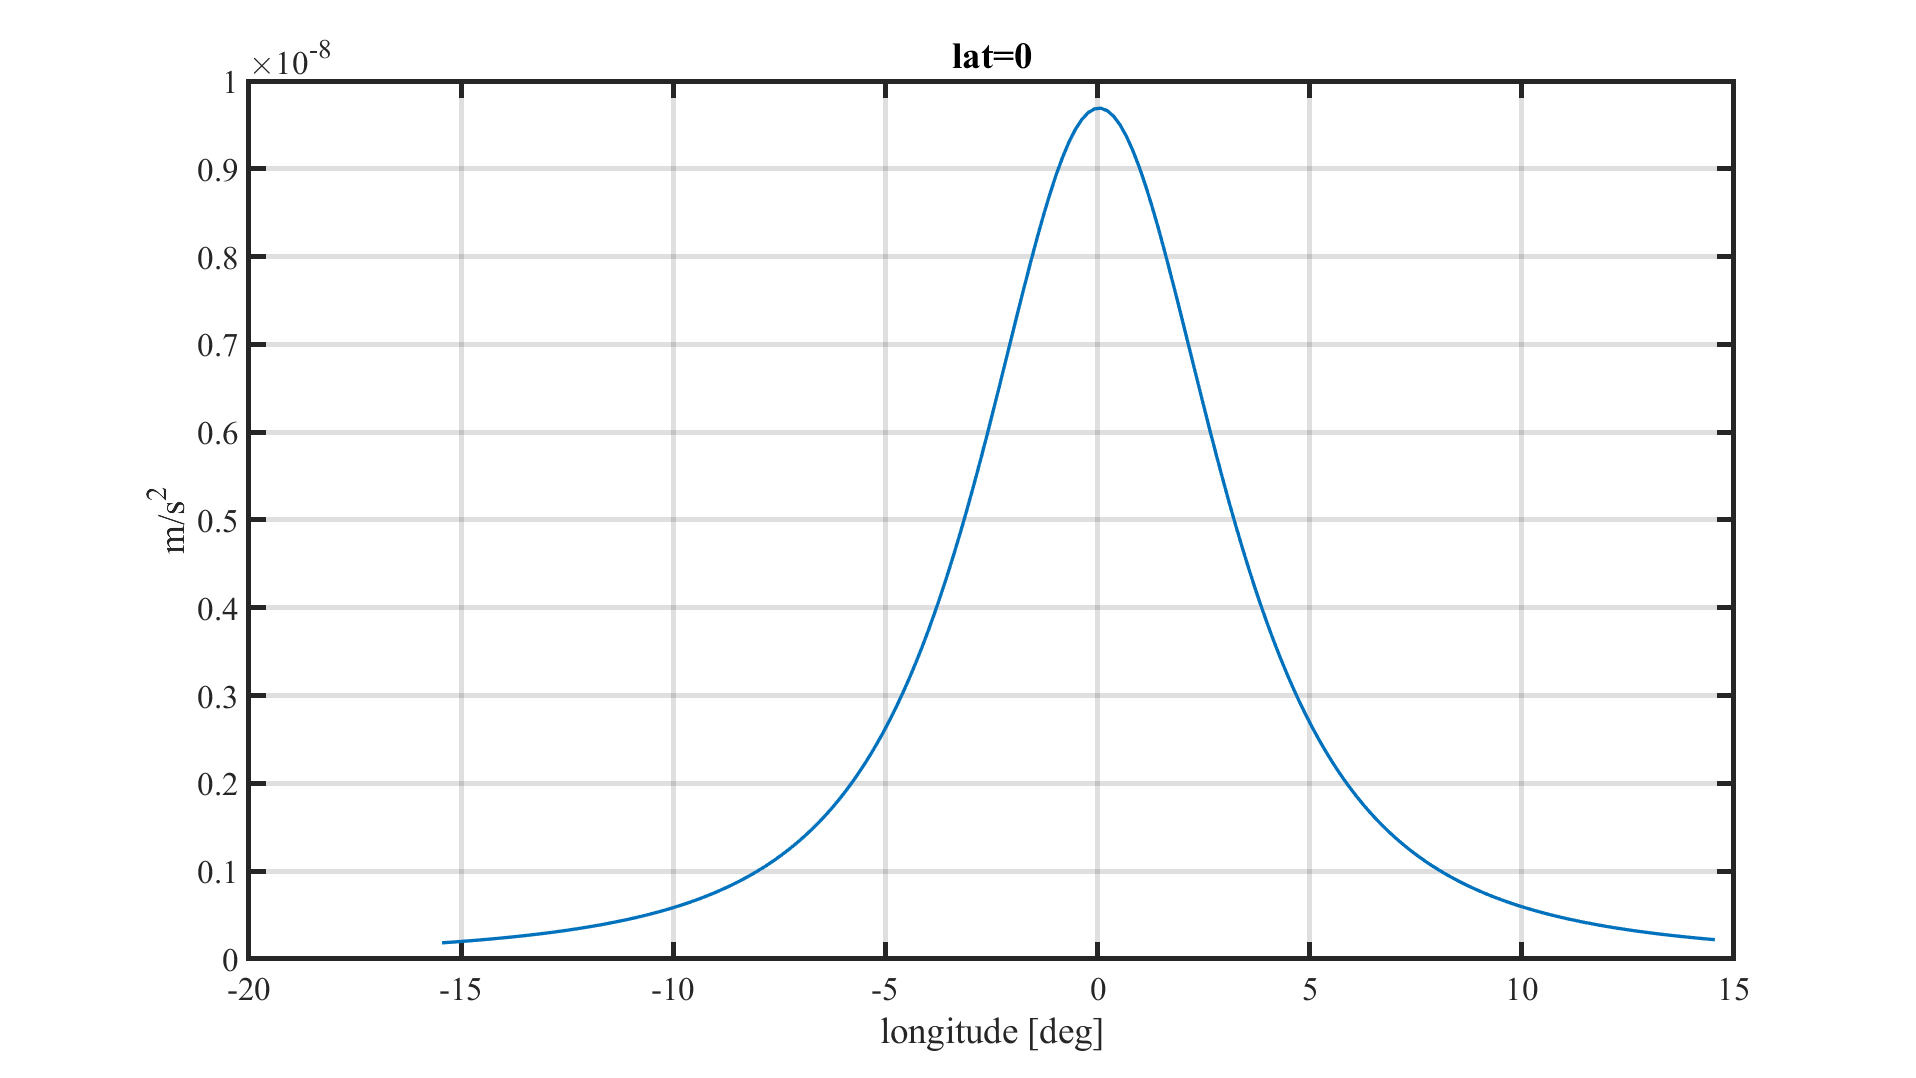

s_coor = importdata("../output/coordinates_sources_syn_xyz.txt");
% compute the acc
los = coor_sate2(:, 1: 3) - coor_sate1(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
acc_rela = zeros(length(coor_sate1), 3);
lgd = zeros(length(coor_sate1), length(s_lon));
lgd_min = zeros(length(s_coor), 1);
for j = 1: length(s_lon)
    for i = 1: length(coor_sate1)
        
        pit1 = coor_sate1(i, :) - s_coor(j, :); 
        pit2 = coor_sate2(i, :) - s_coor(j, :);
        dis1 = sqrt(sum(pit1.^2, 2));
        dis2 = sqrt(sum(pit2.^2, 2));
        f = pit1 / dis1^3 - pit2 / dis2^3;
        f1 = pit1 / dis1^3;
        
        acc_rela(i, :) = G * f * s_mas;
        lgd(i, j) = dot(acc_rela(i, :), los(i, :));
    end
    lgd_min(j) = min(lgd(:, j));
end
% for i = 1: length(coor_sate1)
%     f = zeros(3, length(s_mas));
%     f1 = zeros(3, length(s_mas));
%     for j = 1: length(s_mas)
%         pit1 = coor_sate1(i, :) - s_coor(j, :);
%         pit2 = coor_sate2(i, :) - s_coor(j, :);
%         dis1 = sqrt(sum(pit1.^2, 2));
%         dis2 = sqrt(sum(pit2.^2, 2));
%         f(:, j) = pit1 / dis1^3 - pit2 / dis2^3;
%         f1(:, j) = pit1 / dis1^3;
%     end
%     acc_rela(i, :) = G * f * s_mas;
%     lgd(i) = dot(acc_rela(i, :), los(i, :));
% end
new_figure;
plot(s_lon - 18.8, -lgd_min, "LineWidth", 2); 
grid on;
xlabel("longitude [deg]")
ylabel("m/s^2")
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
title("lat=0")

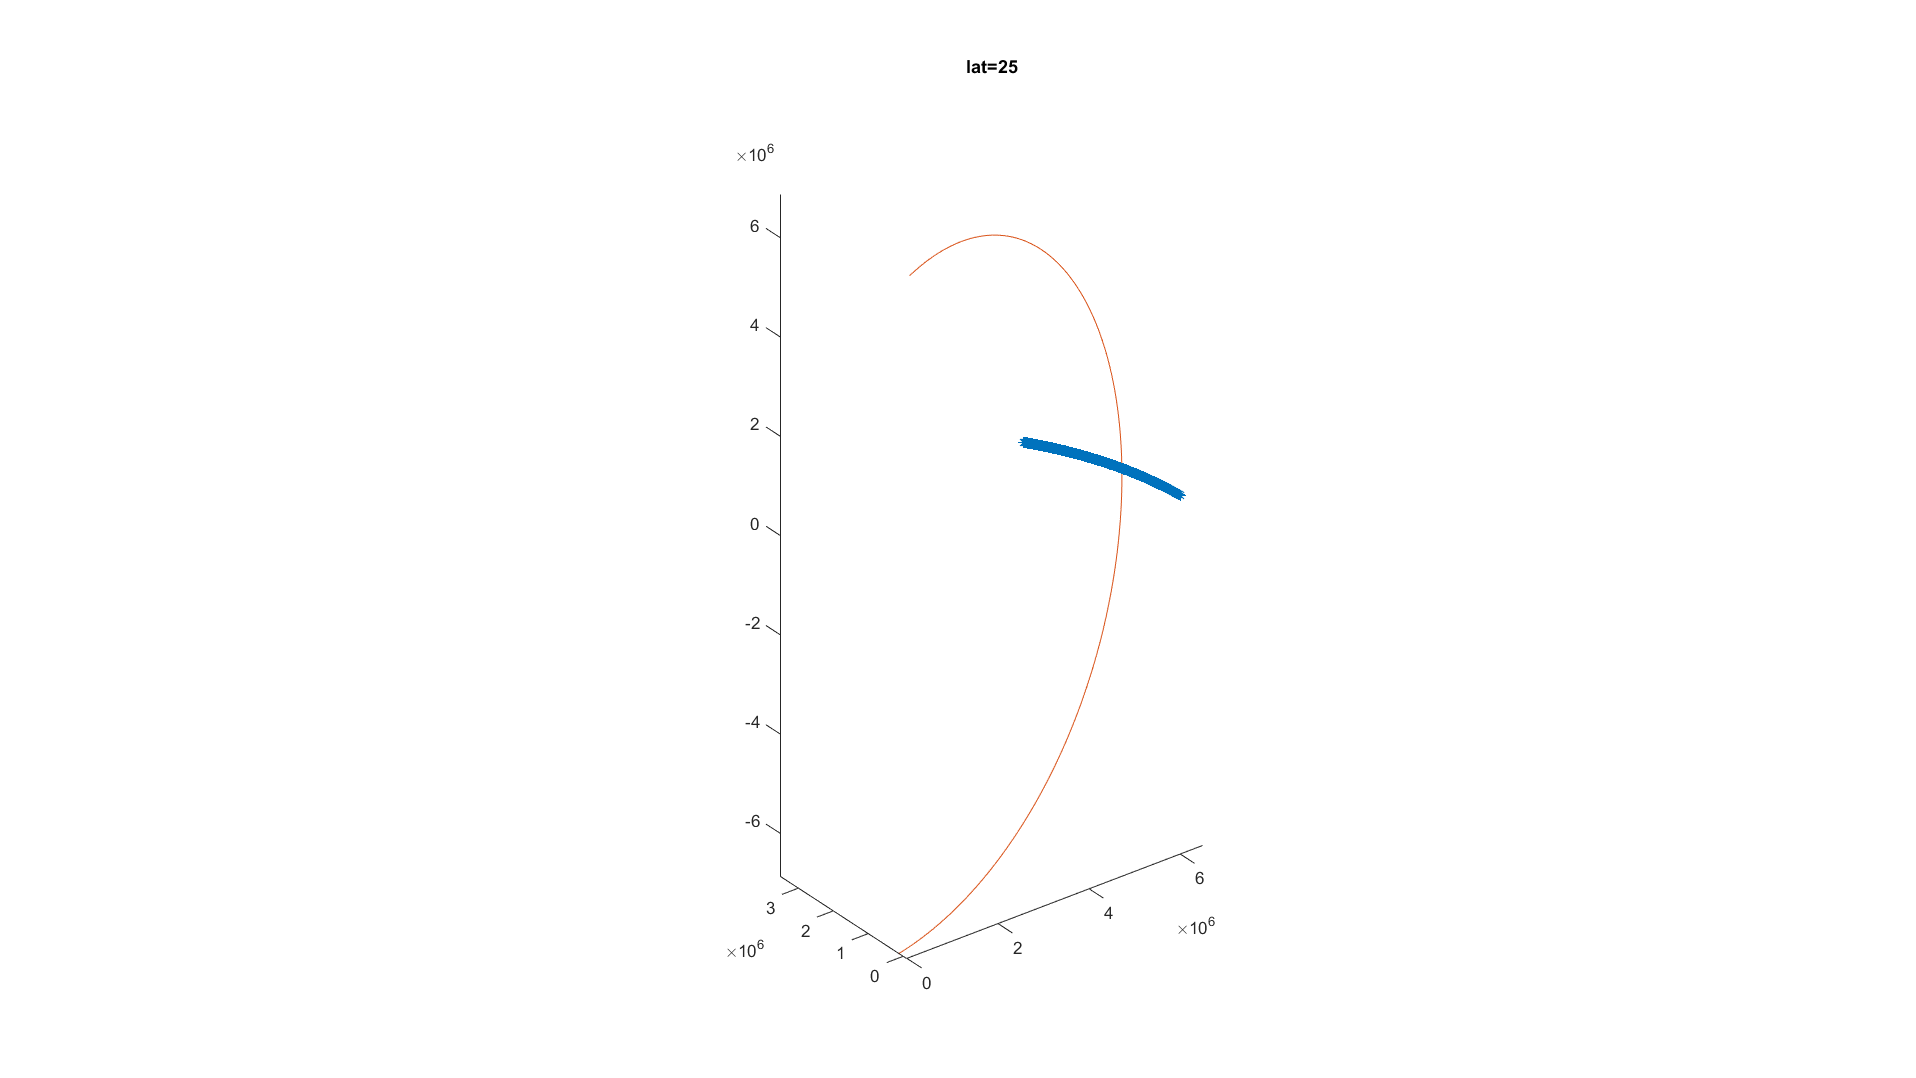

new_figure;
plot3(s_coor(:, 1), s_coor(:, 2), s_coor(:, 3), "*"); hold on
plot3(coor_sate1(:, 1), coor_sate1(:, 2), coor_sate1(:, 3))
axis equal
title("lat=25")